clc; close all; clear all;
Data = load("Prob3.mat");
warning('off', 'all');
% 결과 가독성이 좋지 않아서 경고 문구 제외

## Problem 4.

Probelm 3.과 동일한 데이터에서, 시계열 데이터를 표현하는 운동모델이 ARMAX 구조를 따른다고 가정하자.

### Problem 4-1

모델의 차수에 따른 regressor matrix와 output vector, loss function을 정의하시오.

파라미터 추정을 위해 prediction error method를 기반으로 extended least square estimate을 통해 구하시오.

***Sol)***

ARMAX model에 적용할 수 있는 prediction error method는 아래의 식과 같다.


$$\hat{y}(t|t-1) = (1 - A(q^{-1}))y(t) + B(q^{-1})u(t) + (C(q^{-1}) - 1)\epsilon(t|\theta)$$


where, $\epsilon(t|\theta)=y(t) - \hat{y}(t|t-1;\theta)$

이 때, output model $A(q^{-1})$, input model $B(q^{-1})$, error model $C(q^{-1})$는 다음과 같이 정의된다.

$A(q^{-1}) = 1 + a_1q^{-1} + a_2q^{-2} + \cdots + a_lq^{-l}$, $B(q^{-1}) = b_1q^{-1} + b_2q^{-2} + \cdots + b_mq^{-m}$, $C(q^{-1}) = 1 + c_1q^{-1} + c_2q^{-2} + \cdots + c_nq^{-n}$

그렇다면 regressor matrix는 다음과 같이 정의할 수 있다.

**Regressor matrix**


$$\Phi =\left\lbrack \begin{array}{ccccccccc}
y\left(t-1\right) & \cdots \; & y\left(t-l\right) & u\left(t-1\right) & \cdots  & u\left(t-m\right) & \epsilon \left(t-1\right) & \cdots  & \epsilon \left(t-n\right)\\
y\left(t\right) & \cdots  & t\left(t-l+1\right) & u\left(t\right) & \cdots  & u\left(t-m+1\right) & \epsilon \left(t\right) & \cdots  & \epsilon \left(t-n+1\right)\\
\vdots  & \cdots  & \vdots  & \vdots  & \cdots  & \vdots  & \vdots  & \cdots  & \vdots 
\end{array}\right\rbrack$$


Output vector는 각 model order $l$, $m$, $n$ 중 가장 큰 값 $+ 1$ 부터 시작한다. $k = max(l, m, n) + 1$이라고 했을 때,

**Output vector**


$$y=\left\lbrack \begin{array}{c}
y_k \\
y_{k+1} \\
\vdots \\
y_N 
\end{array}\right\rbrack$$


Loss function은 least-square 추정을 위해서 실제 데이터 $y$와 추정한 모델 파라미터 $\hat{\theta}$를 바탕으로 구한 $\hat{y}(t|\theta)$, 이 둘의 차이의 제곱을 최소로 만들어주는 $\hat{\theta}_N$을 구하는 식으로 설정한다.

**Loss function**

$\hat{\theta}_N = \underset{\theta}{\text{argmin}}\frac{1}{N} \sum \left(y(t) - \hat{y}(t|\theta)\right)^2$ where, $\hat{y}(t|\theta) = \theta^T\varphi(t|\theta)$

#### Deriving prediction error method

ARMAX model : $y(t) = \frac{B(q^{-1})}{A(q^{-1})}u(t) + \frac{C(q^{-1})}{A(q^{-1})}e(t)$, $\left(\frac{B(q^{-1})}{A(q^{-1})} = G(q^{-1}),\quad \frac{C(q^{-1})}{A(q^{-1})} = H(q^{-1})\right)$


$$\hat{y}(t|t-1) = G(q^{-1})u(t) + (1-H(q^{-1})^{-1})(y(t) - G(q^{-1})u(t))$$


                
$$= \frac{B(q^{-1})}{A(q^{-1})}u(t) + \left(1-\frac{A(q^{-1})}{C(q^{-1})}\right)\left(y(t) - \frac{B(q^{-1})}{A(q^{-1})}u(t)\right)$$


                
$$= \frac{B(q^{-1})}{C(q^{-1})}u(t) + \left(1-\frac{A(q^{-1})}{C(q^{-1})}\right)y(t)$$


$C(q^{-1})\hat{y}(t|t-1) = B(q^{-1})u(t) + (C(q^{-1}) - A(q^{-1}))y(t)$ $\Rightarrow$Optimal predictor

**(i)** Pseudo-linear regression form은 다음과 같다.


$$C(q^{-1})\hat{y}(t|t-1;\theta) = B(q^{-1})u(t) + (C(q^{-1}) - A(q^{-1}))y(t)$$



$$\hat{y}(t|t-1;\theta) = \left(1-C(q^{-1})\right)\hat{y}(t|t-1;\theta) + B(q^{-1})u(t) + (C(q^{-1}) - A(q^{-1}))y(t)$$


                   
$$= \left(1-C(q^{-1})\right)\hat{y}(t|t-1;\theta) + B(q^{-1})u(t) + (C(q^{-1})  - A(q^{-1})- 1 + 1)y(t)$$


                   
$$= \left(1 - A(q^{-1})\right)y(t) + B(q^{-1})u(t) + \left(C(q^{-1}) - 1\right)\left(y(t) - \hat{y}(t|t-1;\theta)\right)$$


                   
$$= \left(1 - A(q^{-1})\right)y(t) + B(q^{-1})u(t) + \left(C(q^{-1}) - 1\right)\varepsilon(t|\theta)$$


**Extended least square estimates**

- $C(q^{-1})$이 $1$이라고 처음에 가정한 후 ARX 문제를 푸는 것처럼 $A(q^{-1})$, $B(q^{-1})$의 model 차수를 반영하여 model $\hat{\theta}$를 구한다.

- 이 $\hat{\theta}^{(0)}$은 초기에 추정한 model로 $\hat{\theta}^{(0)}=(\hat{\theta}^T,0,\dots,0)^T$로 설정한다.

- 위의 model parameter들을 바탕으로 $\epsilon(t-1|\theta^{(0)}), \epsilon(t-2|\theta^{(0)}), \dots, \epsilon(t-n|\theta^{(0)})$을 구한다.

- 이 loop를 반복해 위의 cost function을 최소로 만들어주는 model parameter $\hat{\theta}^{(iteration)}$을 구한다.

### Problem 4-2

모델의 order $(n = 1,2,\dots,6)$에 따른 학습 모델과 MSE의 크기를 비교하시오.

이를 통해 가장 적합한 모델이 무엇인지 논의하시오.

***Sol)***

$A(q^{-1})$, $B(q^{-1})$, $C(q^{-1})$ 각각 1부터 6차수 모델을 순회하며 100회씩 $\epsilon$을 업데이트하며 model parameter $\hat{\theta}$를 갱신한다. 함수 `extended_least_square은 이전 step의 `$\epsilon$을 기억하고 있으며, iteration 마다 regressor matrix $\Phi$의 $\epsilon$항들을 갱신해주는 역할을 한다. 

model_order = 1 : 1 : 6;
max_iteration = 100;
MSE_matrix = zeros([6, 6, 6]);
for input_order = model_order
    for output_order = model_order
        for error_order = model_order
            for iter = 1 : max_iteration
                [Phi, estimation_error, theta, A_q, B_q, C_q] = extended_least_square(Data, input_order, output_order, error_order);
            end
            MSE_matrix(input_order, output_order, error_order) = mean_square_error(estimation_error);
            clear functions;
        end
    end
end
error_order1 = MSE_matrix(:, :, 1);
error_order2 = MSE_matrix(:, :, 2);
error_order3 = MSE_matrix(:, :, 3);
error_order4 = MSE_matrix(:, :, 4);
error_order5 = MSE_matrix(:, :, 5);
error_order6 = MSE_matrix(:, :, 6);

[rows, cols] = size(error_order1);
[X, Y] = meshgrid(1:cols, 1:rows);

ErrOrder1 = surf(X, Y, error_order1,'FaceAlpha', 0.1, 'FaceColor','flat');
hold on;
[value, index] = min(error_order1);
[val, idx] = min(value);
[idx, index(idx)]

ans =      1     1


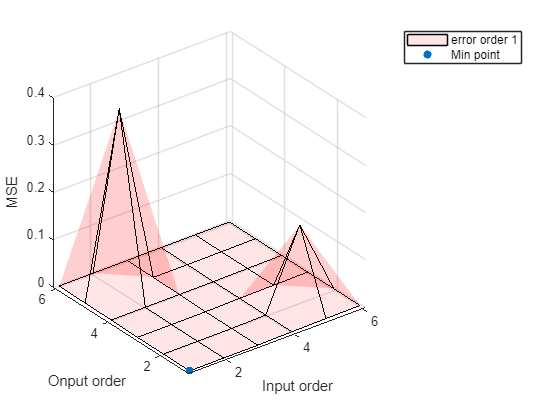

Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off;
ErrOrder1.FaceColor = "red";
xlabel("Input order"); ylabel("Onput order"); zlabel ("MSE");
xlim([0.9, 6.1]); ylim([0.9, 6.1]);
legend([ErrOrder1, Minpoint], {"error order 1", "Min point"})

ErrOrder2 = surf(X, Y, error_order2,'FaceAlpha', 0.1, 'FaceColor','flat');
hold on;
[value, index] = min(error_order2);
[val, idx] = min(value);
[idx, index(idx)]

ans =      1     1


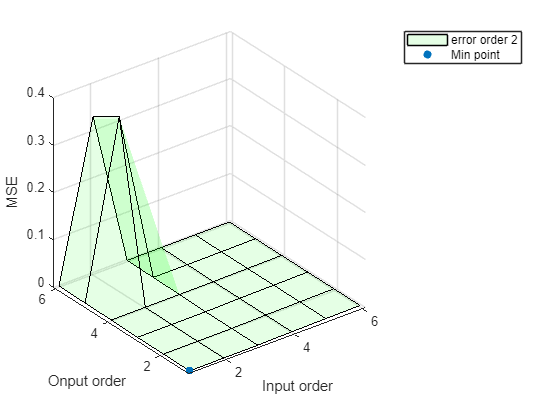

Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off;
ErrOrder2.FaceColor = "green";
xlabel("Input order"); ylabel("Onput order"); zlabel ("MSE");
xlim([0.9, 6.1]); ylim([0.9, 6.1]);
legend([ErrOrder2, Minpoint], {"error order 2", "Min point"})

ErrOrder3 = surf(X, Y, error_order3,'FaceAlpha', 0.1, 'FaceColor','flat');
hold on;
[value, index] = min(error_order3);
[val, idx] = min(value);
[idx, index(idx)]

ans =      1     1


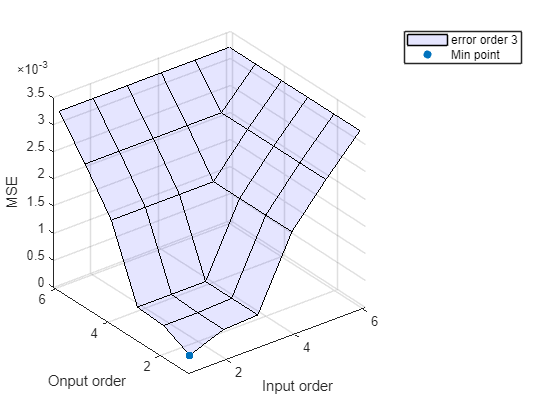

Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off;
ErrOrder3.FaceColor = "blue";
xlabel("Input order"); ylabel("Onput order"); zlabel ("MSE");
xlim([0.9, 6.1]); ylim([0.9, 6.1]);
legend([ErrOrder3, Minpoint], {"error order 3", "Min point"})

ErrOrder4 = surf(X, Y, error_order4,'FaceAlpha', 0.1, 'FaceColor','flat');
hold on;
[value, index] = min(error_order4);
[val, idx] = min(value);
[idx, index(idx)]

ans =      1     1


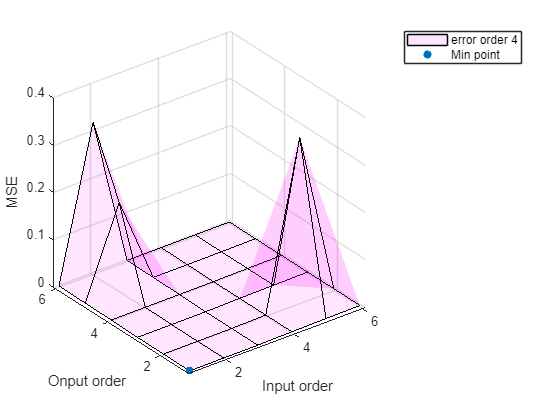

Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off;
ErrOrder4.FaceColor = "magenta";
xlabel("Input order"); ylabel("Onput order"); zlabel ("MSE");
xlim([0.9, 6.1]); ylim([0.9, 6.1]);
legend([ErrOrder4, Minpoint], {"error order 4", "Min point"})

ErrOrder5 = surf(X, Y, error_order5,'FaceAlpha', 0.1, 'FaceColor','flat');
hold on;
[value, index] = min(error_order5);
[val, idx] = min(value);
[idx, index(idx)]

ans =      1     1


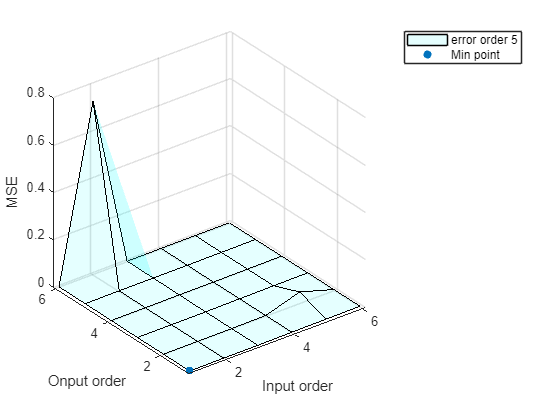

Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off;
ErrOrder5.FaceColor = "cyan";
xlabel("Input order"); ylabel("Onput order"); zlabel ("MSE");
xlim([0.9, 6.1]); ylim([0.9, 6.1]);
legend([ErrOrder5, Minpoint], {"error order 5", "Min point"})

ErrOrder6 = surf(X, Y, error_order6,'FaceAlpha', 0.1, 'FaceColor','flat');
hold on;
[value, index] = min(error_order6);
[val, idx] = min(value);
[idx, index(idx)]

ans =      1     1


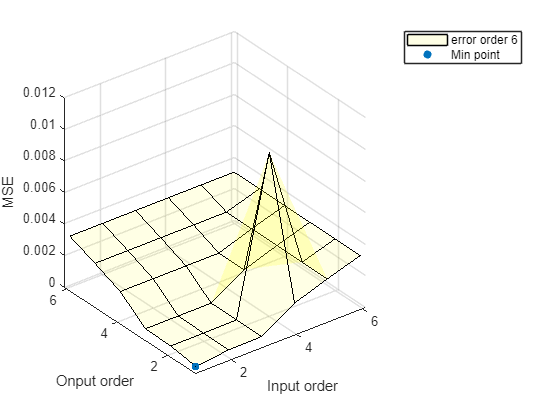

Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off;
ErrOrder6.FaceColor = "yellow";
xlabel("Input order"); ylabel("Onput order"); zlabel ("MSE");
xlim([0.9, 6.1]); ylim([0.9, 6.1]);
legend([ErrOrder6, Minpoint], {"error order 6", "Min point"})

다음 error model order에 따른 MSE 그래프들을 그렸을 때, 공통적으로 input model$A(q^{-1})$와 output model $B(q^{-1})$가 각각 1차일 때 가장 값이 작은 모습을 보였다. MSE의 값 또한 2.903e-04로 공통적인 것으로 보아 모델의 MSE가 동일할 시 모델의 order가 작을 수록 computation cost가 작으므로 error model $C(q^{-1})$는 1차가 적합하다고 할 수 있다. 보통 MSE는 모델의 order가 커질 수록 줄어드는데, Problem 3의 ARX와 Problem 4의 ARMAX 모두 그런 경향성이 나타나지 않은 것을 확인할 수 있다. 오히려 ARMAX 모델의 경우엔 input, output model의 order가 높아질수록 MSE가 커지기에 작은 차수의 model을 선정하는 것이 타당하다고 할 수 있다.

### Problem 4-3

모델의 order별 시스템의 pole과 zero를 복소평면에 나타내고, 시스템의 안정성과 가장 적합한 모델이 무엇인지 논의하시오

***Sol)***

asdf

## Extended least squares estimate

function [Phi, estimation_error, theta, A_q, B_q, C_q] = extended_least_square(data, input_order, output_order, error_order)
    % Data와 input order, output order, error order의 차수를 받아 regressor matrix Phi를 도출
    % data에는 input u, output y가 무조건 존재해야함, 초기 추정 시 ARX 가정 하에서 Phi 도출
    persistent is_first
    persistent epsilon
    persistent zero_epsilon_length
    checkdata(data, input_order, output_order);
    idx = 0;
    if isempty(is_first)
        % If model is estimated in first iter, estimate model in ARX model assumption.
        is_first = 1;
        order = max(input_order, output_order);
        Phi = zeros([length(data.y)-order, input_order+output_order]);
        for i = order+1 : length(data.u)
            idx = idx + 1;
            Phi(idx, :) = [flip(data.y(i-output_order:i-1)'), flip(data.u(i-input_order:i-1)')];
        end
        output_vector = data.y(order+1:end);
        theta = (Phi'*Phi)\Phi'*output_vector;
        A_q = theta(1:output_order)';
        B_q = theta(output_order+1:input_order+output_order)';
        C_q = zeros([error_order,1]);
        epsilon = zeros([length(data.y),1]);
        zero_epsilon_length = order;
        epsilon(order+1:end) = data.y(order+1:end) - Phi * theta;
    else
        order = max([input_order, output_order, error_order]);
        Phi = zeros([length(data.y)-order, input_order+output_order+error_order]);
        for i = zero_epsilon_length+order+1 : length(data.u)
            idx = idx + 1;
            Phi(idx, :) = [flip(data.y(i-output_order:i-1)'), flip(data.u(i-input_order:i-1)'), flip(epsilon(i-error_order:i-1)')];
        end
        output_vector = data.y(order+1:end);
        theta = (Phi'*Phi)\Phi'*output_vector;
        A_q = theta(1:output_order)';
        B_q = theta(output_order+1:input_order+output_order)';
        C_q = theta(input_order+output_order+1:input_order+output_order+error_order);
        epsilon(order+1:end) = data.y(order+1:end) - Phi * theta;
    end
    estimation_error = epsilon;
end

## Check data

function checkdata(data, input_order, output_order)
    if ~isfield(data, 'y') || ~isfield(data, 'u')
        error("Input data must contain y and u");
    end
    % Data field 확인 절차
    if length(data.y) < output_order || length(data.u) < input_order
        error("Insufficient data points in y, u");
    end
    % Data 길이 확인
end

## MSE(Mean Square Error)

function mse = mean_square_error(error)
    mse = (error'*error)/length(error);
end